clc;
close all;
clear all;

% Input sequence
xn = input('Enter the sequence x(n): '); 
N = length(xn); 
xk = zeros(1, N);

% Compute DFT
for k = 0:N-1
    for n = 0:N-1
        xk(k+1) = xk(k+1) + (xn(n+1) * exp(-(1i) * 2 * pi * k * n / N));
    end
end

% Print DFT sequence
disp('DFT Sequence (xk):');

DFT Sequence (xk):


disp(xk);

  10.0000 + 0.0000i   1.0000 + 3.0000i   0.0000 - 0.0000i   1.0000 - 3.0000i




% Plot the input sequence
t = 0:N-1;
subplot(2, 2, 1);
stem(t, xn);
ylabel('Amplitude');
xlabel('Time Index');
title('Input Sequence');
grid on;

% Magnitude Response
magnitude = abs(xk);
t = 0:N-1;
subplot(2, 2, 2);
stem(t, magnitude);
ylabel('Amplitude');
xlabel('K');
title('Magnitude Response for DFT signal');
grid on;

% Phase Response
phase = angle(xk);
t = 0:N-1;
subplot(2, 2, 3);
stem(t, phase);
ylabel('Phase');
xlabel('K');
title('Phase Response for DFT signal');
grid on;

% Compute IDFT
ixk = zeros(1, N); 
for n = 0:N-1
    for k = 0:N-1
        ixk(n+1) = ixk(n+1) + real((xk(k+1) * exp((1i) * 2 * pi * k * n / N)));    
    end
end

% Normalize IDFT result
ixk = ixk ./ N;

% Print IDFT sequence
disp('IDFT Sequence (ixk):');

IDFT Sequence (ixk):


disp(ixk);

    3.0000    1.0000    2.0000    4.0000



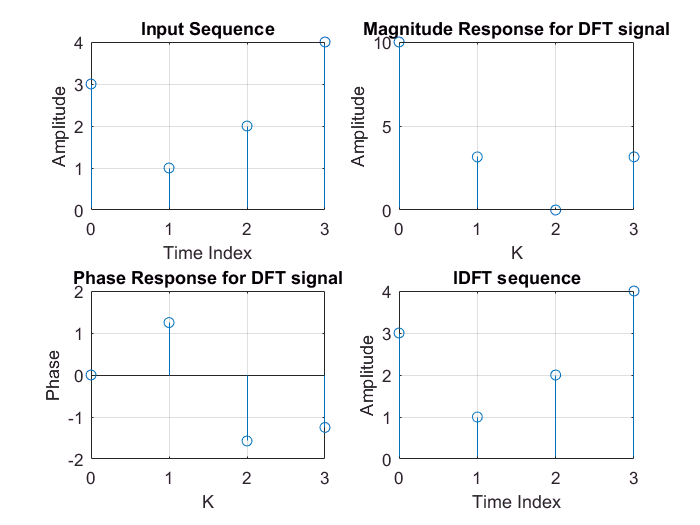


% Plot IDFT sequence
t = 0:N-1;
subplot(2, 2, 4);
stem(t, ixk);
ylabel('Amplitude');
xlabel('Time Index');
title('IDFT sequence');
grid on;